## Import data

import data from ../data/SDSS_merge.dat and FIRST_merge.dat. Total rows are 17,189.


DataFileFolder = '../data/';
SelData = importdata([DataFileFolder,'sdss_merge.dat']);
SDSS = readtable([DataFileFolder,'SDSS_merge.csv']);
FIRST = readtable([DataFileFolder,'FIRST_merge.csv']);

Convert Position angle in range of [-90,90].

DeltaAlpha = deltaPAmodificaiton(SelData(:,6)-SelData(:,7));

% SelData(SelData(:,7)> 90,7) =  SelData(SelData(:,7)> 90,7) - 180;
% SelData(SelData(:,6)>90,6) = SelData(SelData(:,6)>90,6) -180;
SelData(:,7) = PAmodificaiton(SelData(:,7));
SelData(:,6) = PAmodificaiton(SelData(:,6));
SDSS.PA = PAmodificaiton(SDSS.PA);
SDSS.uPA = PAmodificaiton(SDSS.uPA);
SDSS.gPA = PAmodificaiton(SDSS.gPA);
SDSS.iPA = PAmodificaiton(SDSS.iPA);
FIRST.PA = PAmodificaiton(FIRST.PA);


Con = SelData(:,8);
rMag = SelData(:,4);
uMag = SelData(:,5);
baxis = SelData(:,19);
aaxis = SelData(:,18);
paSDSS = SelData(:,7) ;
paFIRST = SelData(:,6);
PAdiff = deltaPAmodificaiton(SDSS.PA - FIRST.PA);

bins = 6;
Edge180 = linspace(-90,90,bins+1);
Edge90 = linspace(0,90,bins+1);

### Figure 8 Scatter plot of t − r versus C2

#### AB radio magnitude

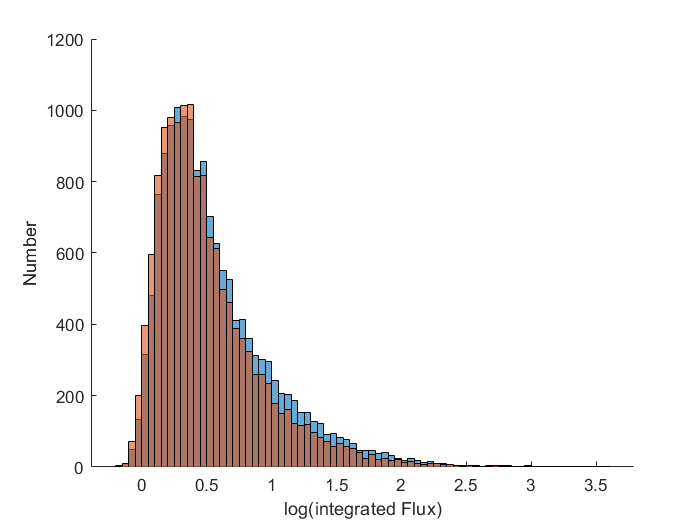

tMag = -2.5.*log10(  SelData(:,3)/1d3 ./ 3631);
tMine = -2.5.*log10(  FIRST.Fint/1d3 ./ 3631);
C2 = C2function(Con , uMag,rMag);
figure
hold on 
histogram(log10(FIRST.Fint))
histogram(log10(SelData(:,3)))
xlabel('log(integrated Flux)')
ylabel('Number')

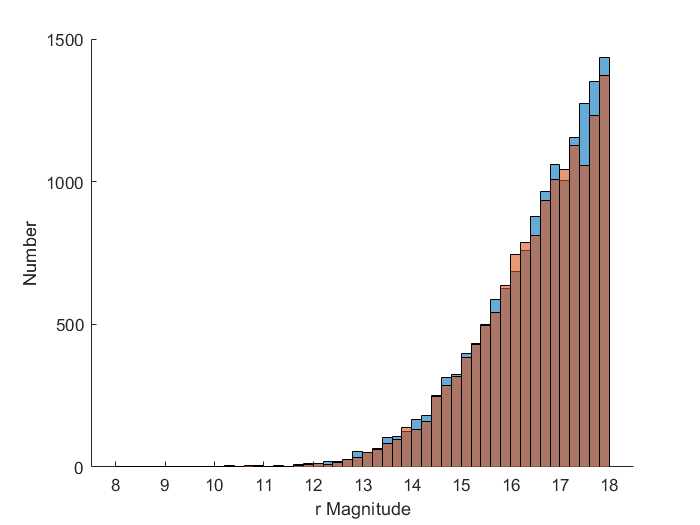


figure
hold on 
histogram(SDSS.r)
histogram(rMag)
xlabel('r Magnitude')
ylabel('Number')

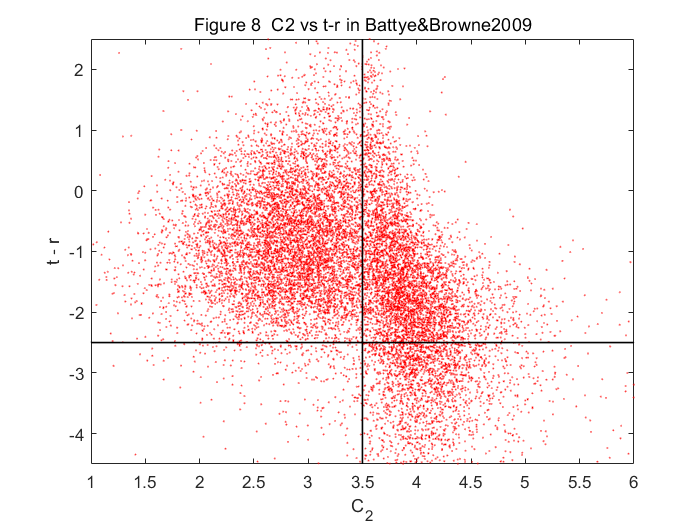


figure
plot(C2,tMag - rMag,'.r','MarkerSize',0.5);
hold on
h = ezplot('y=-2.5 + x*0');
h.LineWidth = 1;h.LineColor = 'k';
h = ezplot('x =3.5 + y*0');
h.LineWidth = 1;h.LineColor = 'k';
xlim([1 6]); ylim([-4.5 2.5])
xlabel('C_2');ylabel('t - r');
title('Figure 8  C2 vs t-r in Battye&Browne2009')

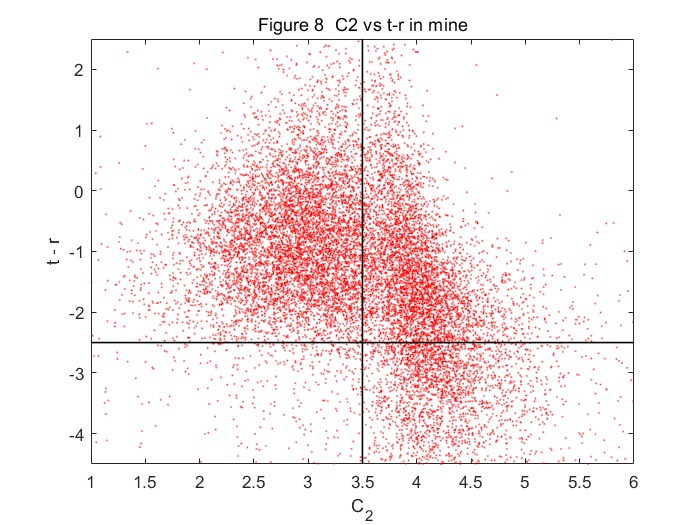

C2mine = (0.3130*SDSS.concentration +  ...
    0.9498*(SDSS.u - SDSS.r));
figure
plot(C2mine,tMine - SDSS.r ,'.r','MarkerSize',0.5);
hold on
h = ezplot('y=-2.5 + x*0');
h.LineWidth = 1;h.LineColor = 'k';
h = ezplot('x =3.5 + y*0');
h.LineWidth = 1;h.LineColor = 'k';
xlim([1 6]); ylim([-4.5 2.5])
xlabel('C_2');ylabel('t - r');
title('Figure 8  C2 vs t-r in mine')

### Figure 9 split PA by t-r 

figure
SelectedRow = C2 > 3.5 &((tMag - rMag )>-2.5) & BoverAsdss <0.6;

函数或变量 'BoverAsdss' 无法识别。

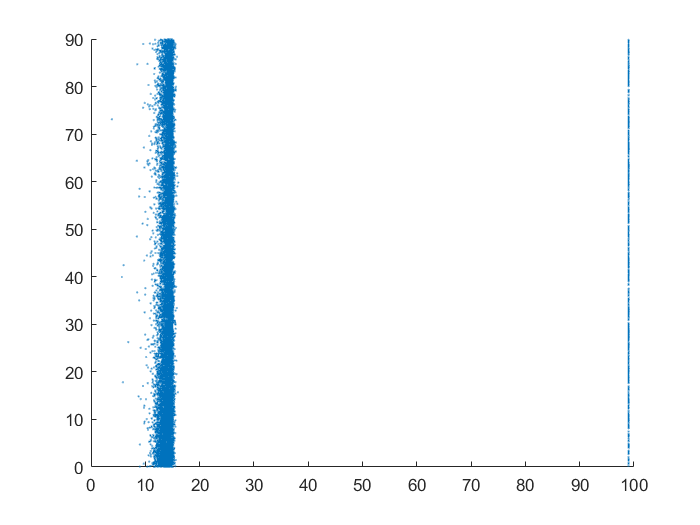

[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
SelectedRow = C2mine > 3.5 & (tMine - SDSS.r )>-2.5 & SDSS.BA < 0.6;
[h2,e2] = histerror(PAdiff(SelectedRow),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([100 480])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 7 C2>3.5 t-r> -2.5 b/a < 0.6')
hold off
figure
SelectedRow = C2 > 3.5 &((tMag - rMag )<-2.5) & BoverAsdss <0.6;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
SelectedRow = C2mine > 3.5 & (tMine - SDSS.r )<-2.5 & SDSS.BA < 0.6;
[h2,e2] = histerror(PAdiff(SelectedRow),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([30 120])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 7 C2>3.5 t-r< -2.5 b/a < 0.6')
hold off
figure
SelectedRow = C2 > 3.5 &((tMag - rMag )>-2.5) & BoverAsdss >0.6;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
SelectedRow = C2mine > 3.5 & (tMine - SDSS.r )>-2.5 & SDSS.BA > 0.6;
[h2,e2] = histerror(PAdiff(SelectedRow),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([450 850])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 7 C2>3.5 t-r > -2.5 b/a >  0.6')
hold off
figure
SelectedRow = C2 > 3.5 &((tMag - rMag )<-2.5) & BoverAsdss >0.6;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
SelectedRow = C2mine > 3.5 & (tMine - SDSS.r )<-2.5 & SDSS.BA > 0.6;
[h2,e2] = histerror(PAdiff(SelectedRow),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([260 450])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 7 C2>3.5 t-r< -2.5 b/a >  0.6')
hold off

## Section 3.4 Spectoscopic identificaitons

### Figure 10          m

### Figure 11 Different kinds of spectra

### Functions 

function c1 = C1function(c,u,r)
c1 = 0.965.*c - 0.262.*(u-r);
end
function c2 = C2function(c,u,r)
% C2function(c,u,r)
c2 = 0.262.*c + 0.965.*(u-r);
end

function PAmod = PAmodificaiton(PA)
check =sum(PA < -270 )+sum(PA > 270 );
if( check>0)
fprintf('warning %i Position angle are out of range. max: %f ; min: %f' ...
    ,check,max(PA),min(PA))

end
PA(PA>90) = PA(PA>90)  - 180;
PA(PA<-90) = PA(PA<-90)  + 180;
PAmod = PA;
end
function deltaPAmod = deltaPAmodificaiton(deltaPA)
deltaPA(deltaPA<0) = -deltaPA(deltaPA<0);
deltaPA(deltaPA>90) = 180- deltaPA(deltaPA>90);

deltaPAmod = deltaPA;
end